# Visualization of the activation layer of a CNN 

This example shows how to visualize the activation layers of the trained CNN net_micro_train280_epochs500_acc88_500epochs.map (trained with the code shown in Lecture10_demo_train_CNN.mlx)

clear
close all

We load the the test set , to get some images where to evaluate the activation functions of the CNN

dataset_path='/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Test'

dataset_path = '/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Test'

imdsValidation = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

Select and show an image of the Test set with microcalcification:

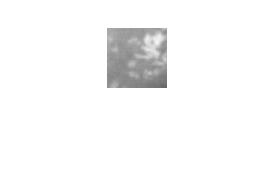

im=readimage(imdsValidation,300); % scelgo un immagine con micro
figure, imshow(im)

Random selection of 9 images with microcalcifications

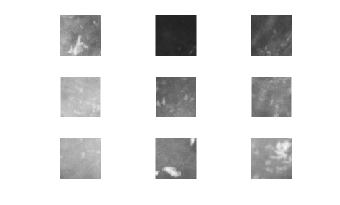

images_Label1=imdsValidation.Files(imdsValidation.Labels=='1');
figure;
perm = randperm(size(images_Label1,1),9);
for i = 1:9
    subplot(3,3,i);
    imshow(images_Label1{perm(i)});
end

We load a network that I have pretrained with 500 epochs, which achieved on the validation set an accuracy of 88%. 

load net_micro_train280_epochs500_acc88_500epochs

**View Network Architecture**

Display the layers of the network to see which layers you can look at. The convolutional layers perform convolutions with learnable parameters. The network learns to identify useful features, often with one feature per channel. Observe that the first convolutional layer has 8 channels.

net.Layers

ans =   15×1 Layer array with layers:

     1   'imageinput'    Image Input             60×60×1 images with 'zerocenter' normalization
     2   'conv_1'        2-D Convolution         8 3×3×1 convolutions with stride [1  1] and padding 'same'
     3   'batchnorm_1'   Batch Normalization     Batch normalization with 8 channels
     4   'relu_1'        ReLU                    ReLU
     5   'maxpool_1'     2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2'        2-D Convolution         16 3×3×8 convolutions with stride [1  1] and padding 'same'
     7   'batchnorm_2'   Batch Normalization     Batch normalization with 16 channels
     8   'relu_2'        ReLU                    ReLU
     9   'maxpool_2'     2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'conv_3'        2-D Convolution         32 3×3×16 convolutions

The Image Input layer specifies the input size. You can resize the image before passing it through the network, but the network also can process larger images. If you feed the network larger images, the activations also become larger. However, since the network is trained on images of size 60-by-60, it is not trained to recognize objects or features larger than that size.

We can also use

analyzeNetwork(net)

## **Show Activations of First Convolutional Layer**

Investigate features by observing which areas in the convolutional layers activate on an image and comparing with the corresponding areas in the original images. Each layer of a convolutional neural network consists of many 2-D arrays called *channels*. Pass the image through the network and examine the output activations of the `conv_1` layer.

act1 = activations(net,im,'conv_1');

The activations are returned as a 3-D array, with the third dimension indexing the channel on the `conv1` layer. To show these activations using the `imtile` function, reshape the array to 4-D. The third dimension in the input to `imtile `represents the image color. Set the third dimension to have size 1 because the activations do not have color. The fourth dimension indexes the channel.

sz = size(act1)

sz =     60    60     8


act1 = reshape(act1,[sz(1) sz(2) 1 sz(3)]);

Now you can show the activations. Each activation can take any value, so normalize the output using `mat2gray`. All activations are scaled so that the minimum activation is 0 and the maximum is 1. Display the 8 images on an 2-by-4 grid, one for each channel in the layer.

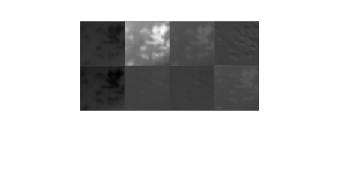

figure;
I = imtile(mat2gray(act1),'GridSize',[2 4]);
imshow(I)

**Investigate the Activations in Specific Channels**

Each tile in the grid of activations is the output of a channel in the `conv1` layer. White pixels represent strong positive activations and black pixels represent strong negative activations. A channel that is mostly gray does not activate as strongly on the input image. The position of a pixel in the activation of a channel corresponds to the same position in the original image. A white pixel at some location in a channel indicates that the channel is strongly activated at that position.

Resize the activations in channel 8 to have the same size as the original image and display the activations.

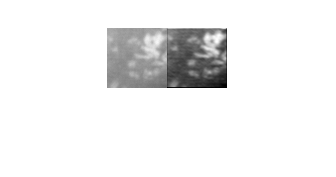

act1ch8 = act1(:,:,:,8);
act1ch8 = mat2gray(act1ch8);
act1ch8 = imresize(act1ch8,size(im));

I = imtile({im,act1ch8});
imshow(I)

**Find the Strongest Activation Channel**

You also can try to find interesting channels by programmatically investigating channels with large activations. Find the channel with the largest activation using the `max` function, resize, and show the activations.

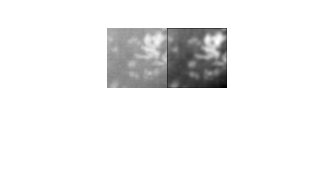

[maxValue,maxValueIndex] = max(max(max(act1)));
act1chMax = act1(:,:,:,maxValueIndex);
act1chMax = mat2gray(act1chMax);
act1chMax = imresize(act1chMax,size(im));
figure
I = imtile({im,act1chMax});
imshow(I)

**Investigate a Deeper Layer**

Most convolutional neural networks learn to detect features like color and edges in their first convolutional layer. In deeper convolutional layers, the network learns to detect more complicated features. Later layers build up their features by combining features of earlier layers. Investigate the `conv_3` layer in the same way as the `conv_1` layer. Calculate, reshape, and show the activations in a grid.

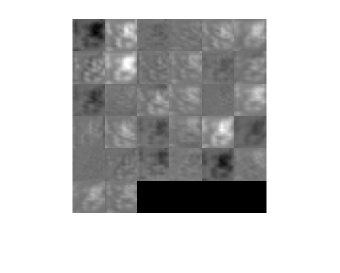

act3 = activations(net,im,'conv_3');
sz = size(act3);
act3 = reshape(act3,[sz(1) sz(2) 1 sz(3)]);

I = imtile(imresize(mat2gray(act3),[48 48]));
imshow(I)

There are too many images to investigate in detail, so we will focus on some of the more interesting ones. Display the strongest activation in the `conv3` layer.

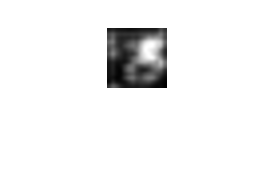

[maxValue3,maxValueIndex3] = max(max(max(act3)));
act3chMax = act3(:,:,:,maxValueIndex3);
imshow(imresize(mat2gray(act3chMax),size(im)))

Many of the channels contain areas of activation that are both light and dark. These are positive and negative activations, respectively. However, only the positive activations are used because of the rectified linear unit (ReLU) that follows the `conv_3` layer. To investigate only positive activations, repeat the analysis to visualize the activations of the `relu_3` layer.

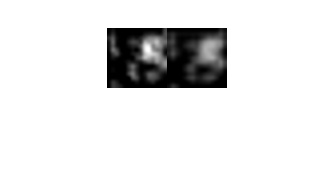

act3relu = activations(net,im,'relu_3');
sz = size(act3relu);
act3relu = reshape(act3relu,[sz(1) sz(2) 1 sz(3)]);

I = imtile(imresize(mat2gray(act3relu(:,:,:,[2 8])),size(im)));
imshow(I)